load spectra
who


Your variables are:

CIED50       R1           Tungsten60W  ans          f11          wavelength   
CIED65       R2           XYZ          chips20      plank90K     xyz          



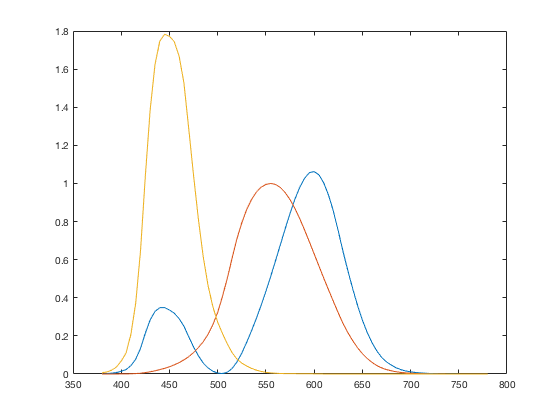

plot(wavelength,xyz);

[x1,y1,z1] = spectra2xyz(R1,CIED65)

x1 = 40.0489

y1 = 49.7395

z1 = 26.6104

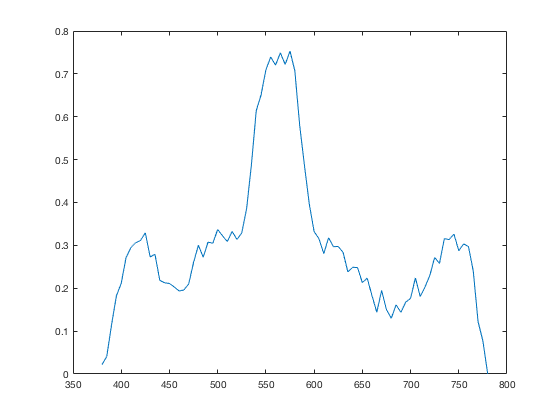


plot(wavelength,R1);

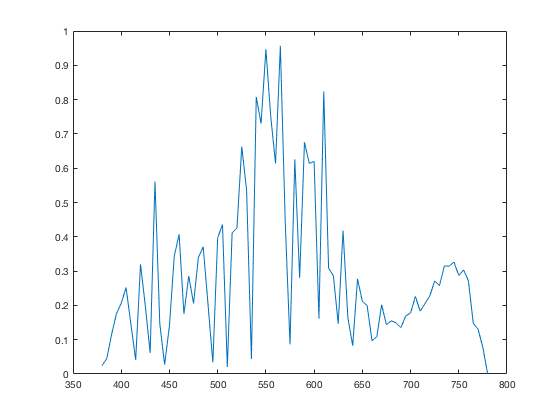

plot(wavelength,R2);

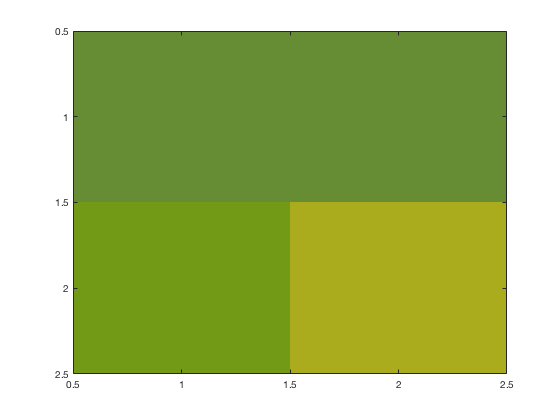


[x2,y2,z2] = spectra2xyz(R2,CIED65);
[x3,y3,z3] = spectra2xyz(R1,f11);
[x4,y4,z4] = spectra2xyz(R2,f11);

[r1,g1,b1] = myxyz2rgb(x1,y1,z1);
[r2,g2,b2] = myxyz2rgb(x2,y2,z2);
[r3,g3,b3] = myxyz2rgb(x3,y3,z3);
[r4,g4,b4] = myxyz2rgb(x4,y4,z4);
map = [r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4];
map=min(1,max(0,map));
image([1 2; 3 4]);
colormap(map);

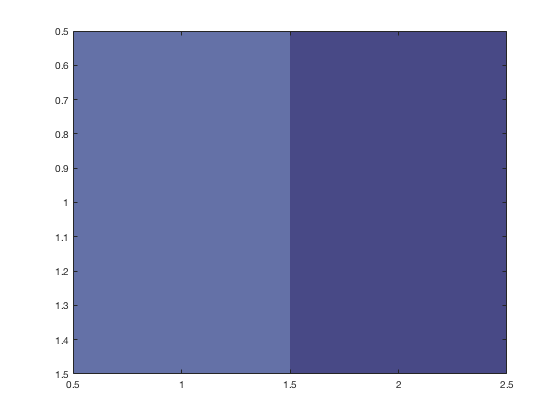

clear
%dot on dot
[r1,g1,b1] = myxyz2rgb(43.915,44.87,68.43);
%dot off dot
[r2,g2,b2] = myxyz2rgb(31.6,30.48,54.2);
map = [r1 g1 b1; r2 g2 b2];
map=min(1,max(0,map));
image([1 2]);
colormap(map);

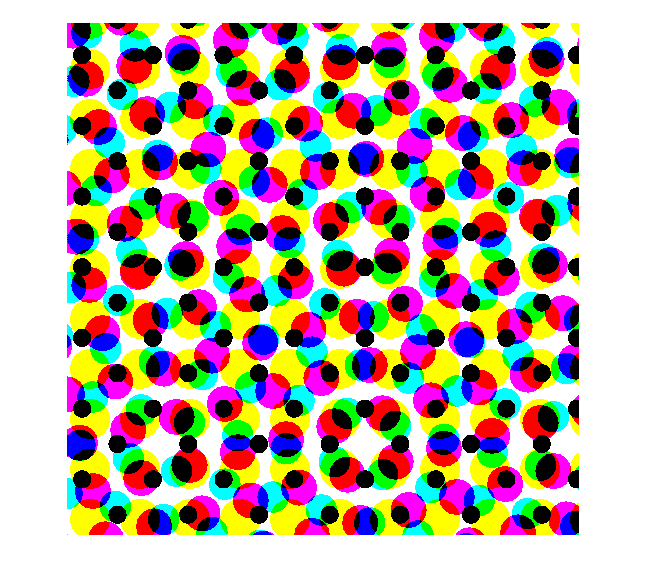

[C, M, Y, K]=tiffread('halftone.tif');
[R, G, B]=cmyk2rgb(C, M, Y, K);
imshowrgb(R, G, B);

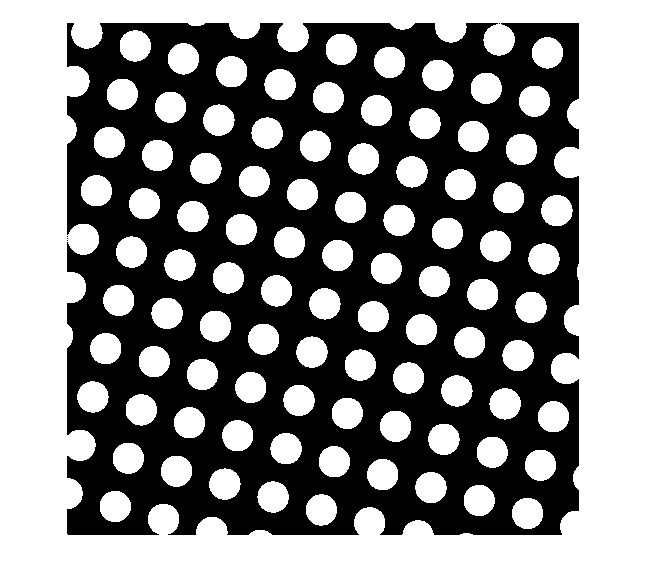

imshow(C);

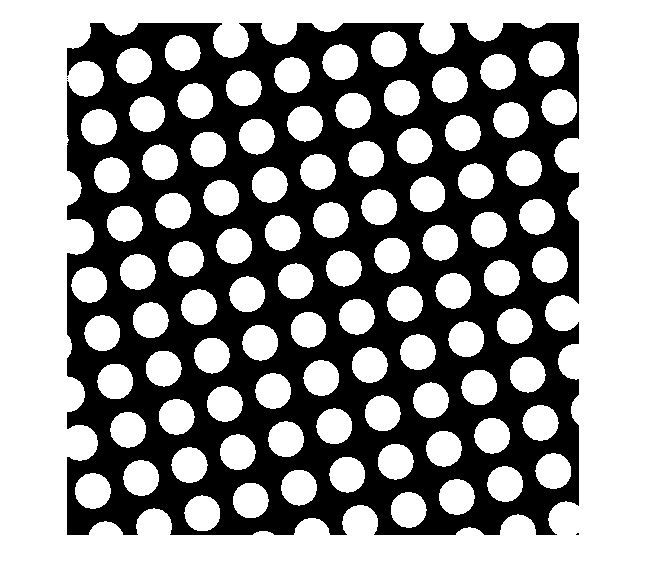

imshow(M);

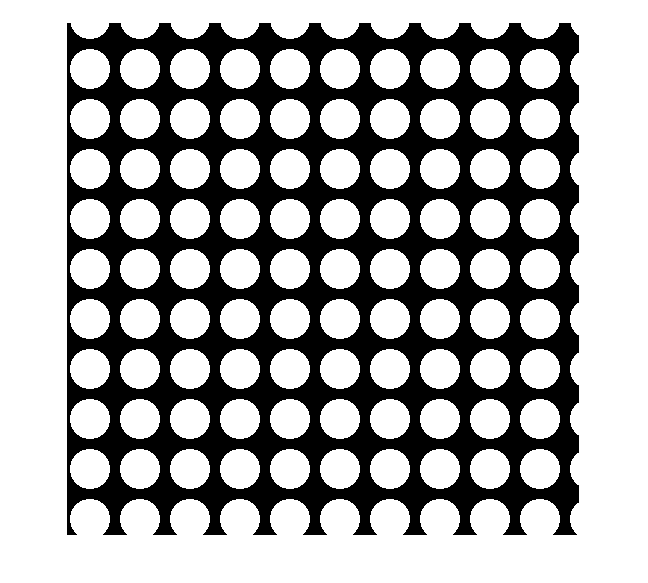

imshow(Y);

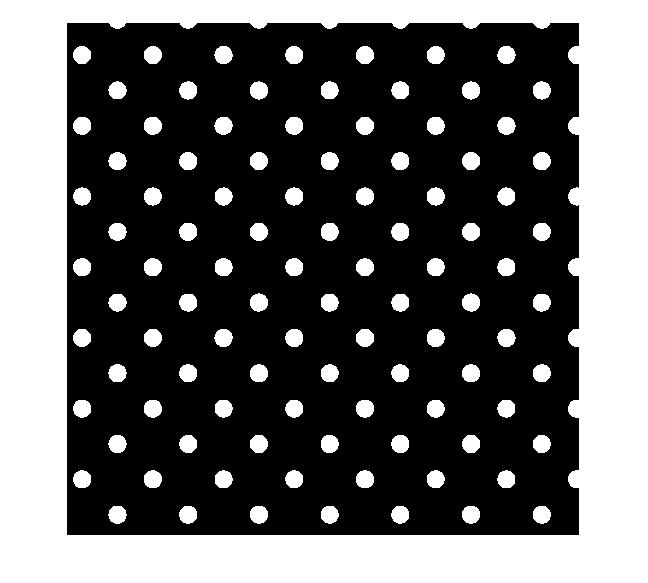

imshow(K);

CyanMagenta = sum(sum(C & M & ~Y & ~K))/512^2;
C1=C(139:394,129:384);
M1=M(139:394,129:384);
Y1=Y(139:394,129:384);
K1=K(139:394,129:384);
Demichel_test(C1,M1,Y1,K1);

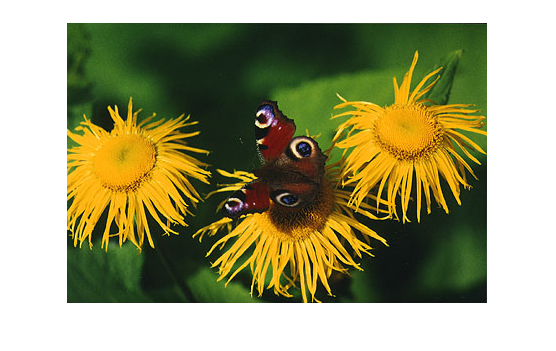

[R, G, B]=tiffread('butterfly.tif');
imshowrgb(R ,G, B)

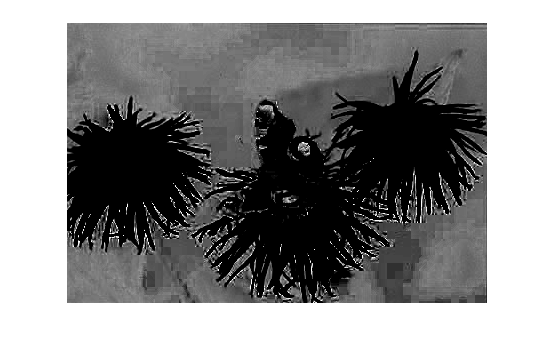

[C, M, Y, K]=rgb2cmyk(R,G,B);
figure(1);
imshow(C);

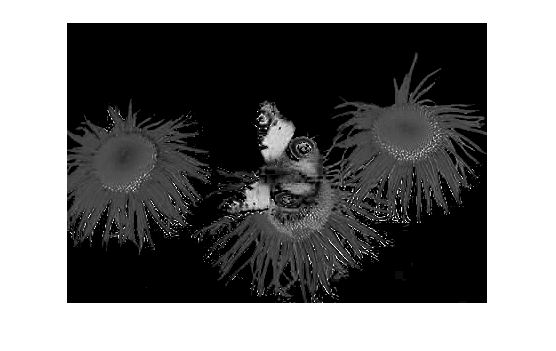

figure(2);
imshow(M);

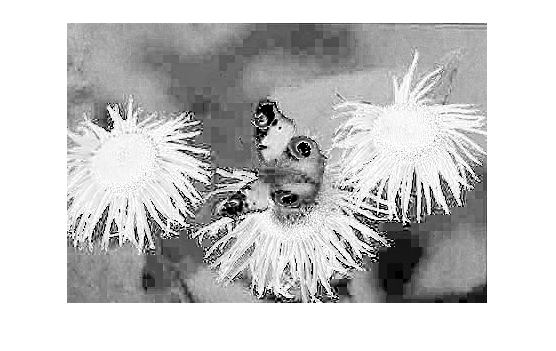

figure(3);
imshow(Y);

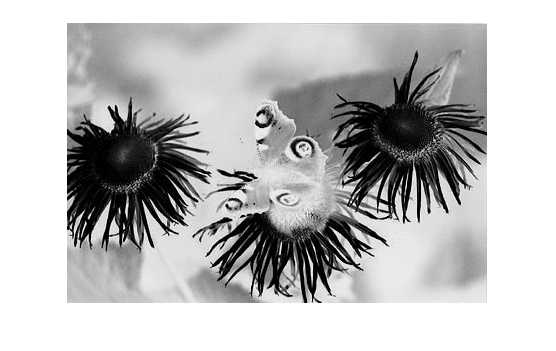

figure(4);
imshow(K);

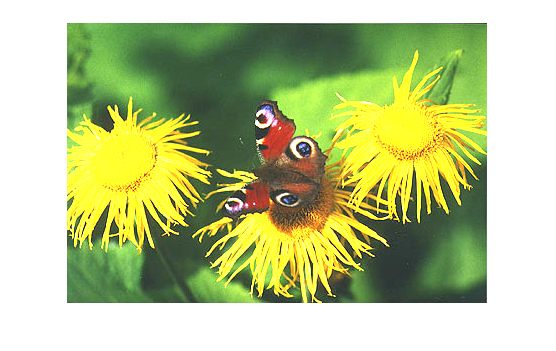

[L, a, b]=myrgb2lab(R,G,B);
[R2, G2, B2]=mylab2rgb(L+20, a, b);
imshowrgb(R2, G2, B2);

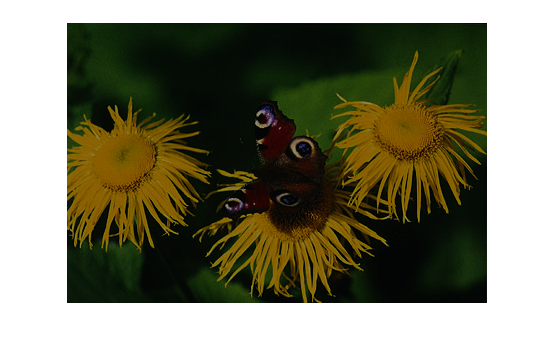

[R3, G3, B3]=mylab2rgb(L-20, a, b);
imshowrgb(R3, G3, B3);

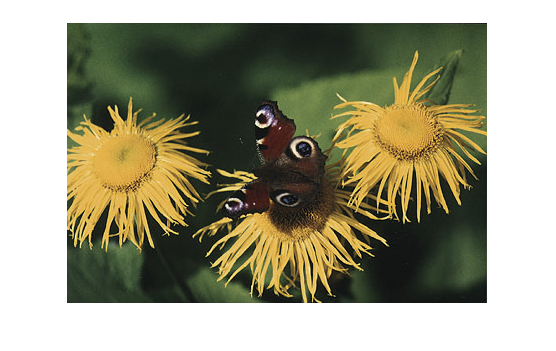



[R4, G4, B4]=mylab2rgb(L, 0.5*a, 0.5*b);
[R5, G5, B5]=mylab2rgb(L, 3*a, 3*b);
imshowrgb(R4, G4, B4);

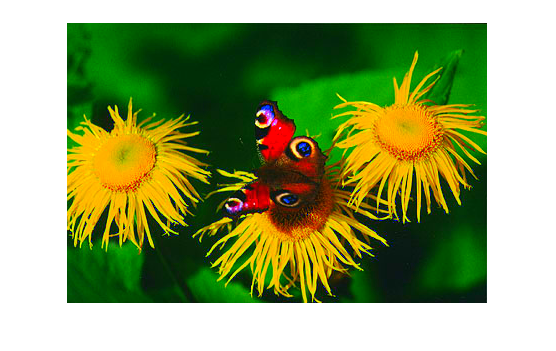

imshowrgb(R5, G5, B5);

load spectra.mat
[x1,y1,z1] = spectra2xyz(1,CIED65)

x1 = 95.0437

y1 = 100

z1 = 108.8818

[r1,g1,b1] = myxyz2rgb(x1,y1,z1);
[x2,y2,z2] = spectra2xyz(1,Tungsten60W)

x2 = 112.9853

y2 = 100.0000

z2 = 28.5810

[r2,g2,b2] = myxyz2rgb(x2,y2,z2);
[x3,y3,z3] = spectra2xyz(1,plank90K)

x3 = 97.0578

y3 = 100

z3 = 141.1759

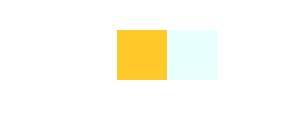

[r3,b3,g3] = myxyz2rgb(x3,y3,z3);
map = [r1 g1 b1; r2 g2 b2; r3 g3 b3];
map=min(1,max(0,map));
%image([1 2; 3 4]);
%colormap(map);
showRGB(map)

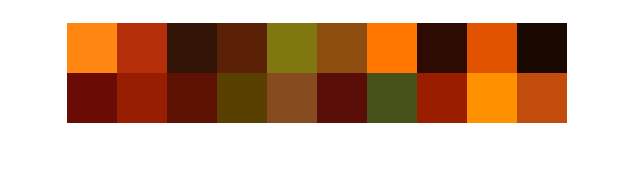

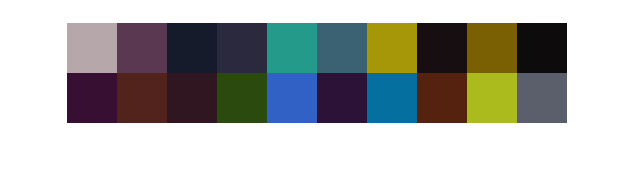

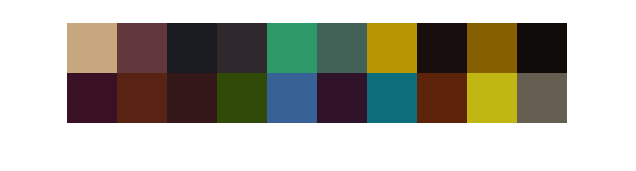

showRGB_20();

ans =    42.6575   37.7851    9.2111


ans =    35.5059   37.1884   45.1131


ans =    35.1115   37.2965   34.8667


ans =    67.8620   67.4182   67.4989


ans =     0.1015   -1.7637   -1.0122


ans =     7.4954    6.9190    7.0603


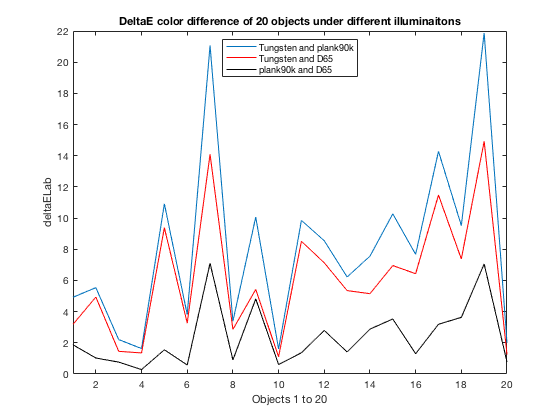

plot_deltaE();

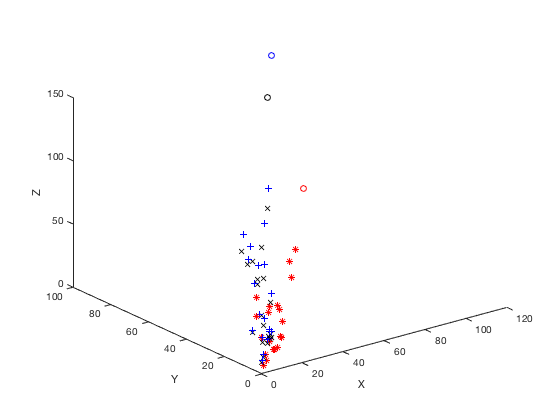

plot_XYZ();

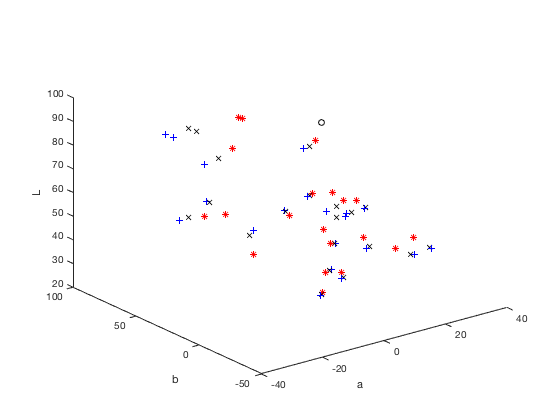

plot_Lab();